# МЕТОДЫ ОПТИМИЗАЦИИ

### Семинар 9. Линейная регрессия

В терминах машинного обучения, регрессия - это "supervised learning"

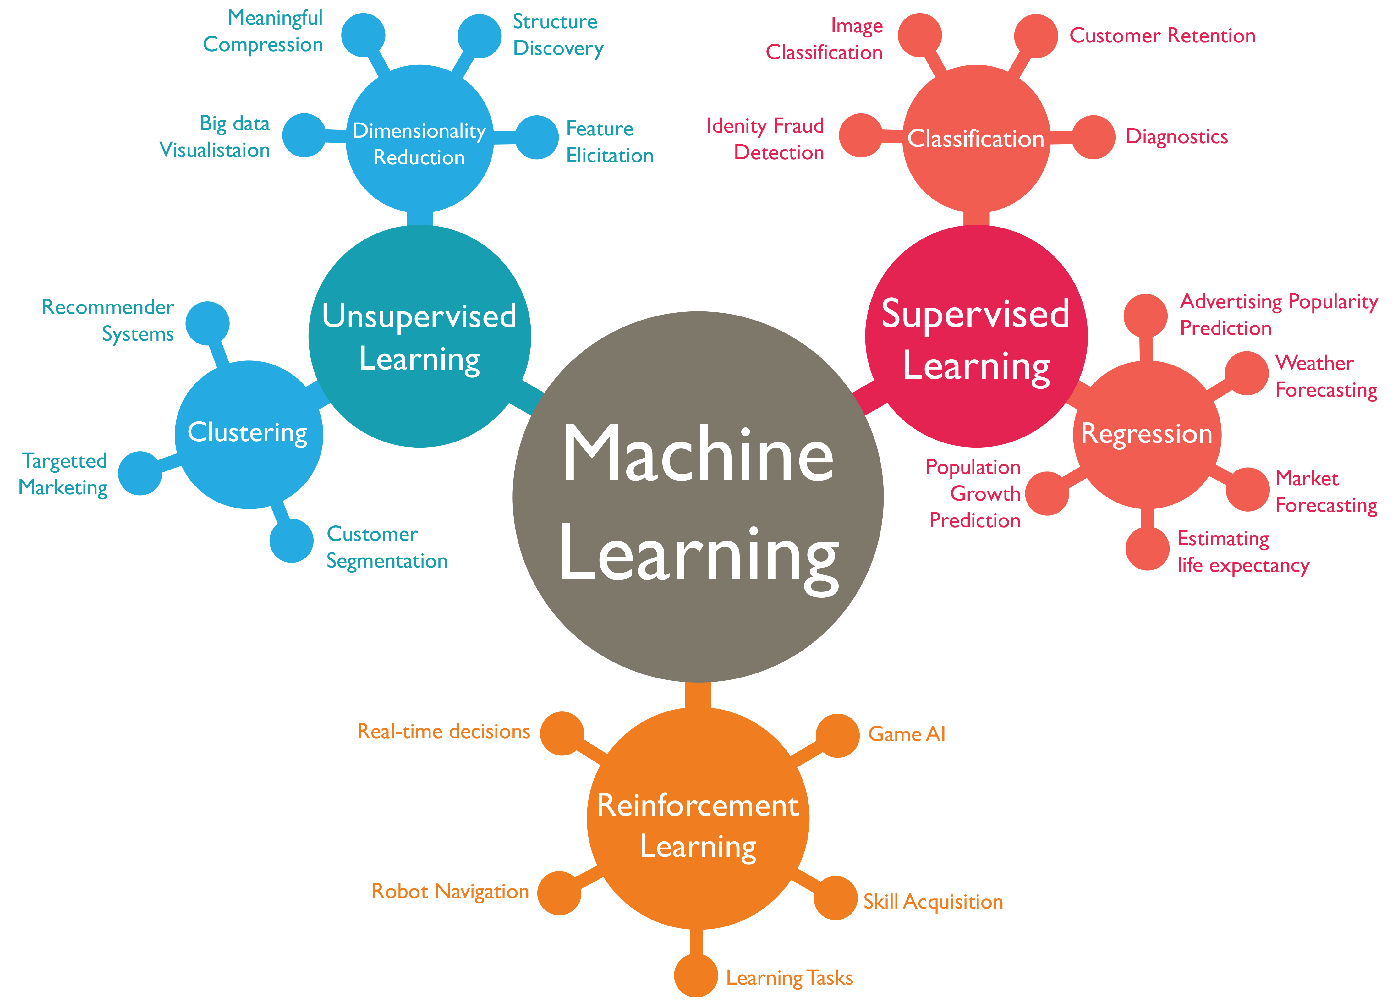

(https://github.com/shanmukh05/Machine-Learning-Roadmap

youtube: AI Warehouse - reinforcement learning)

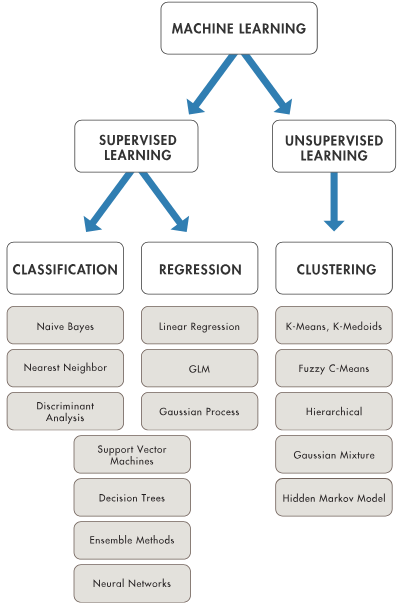

(https://www.mathworks.com/solutions/machine-learning.html)

#### Задача линейной регрессии в обозначениях статистики

В предыдущем семинаре был вектор $\vec{e}$ - вектор, который лежит в нуль-пространстве матрицы $A^T$, это та часть вектора $\vec{b}$, которая не может быть описана в рамках модели $A\vec{x}=\vec{b}$. 

$\vec{e}=\vec{b} - \vec{p}$, где $\vec{p} = AA^{\dagger}\vec{b}$ - наиболее близкий (в терминах квадратичного отклонения) к $\vec{b}$вектор, лежащий в пространстве столбцов матрицы $A$. Если $\vec{b}$ изначально лежит в пространстве столбцов $C(A)$ (и все столбцы линейнонезависимы), то $AA^{\dagger}\vec{b}=\vec{b}$, наша модель описывает данные полностью, без ошибки.

Теперь появляется случаяная составляющая, вектор $\vec{e}$ будет иметь случайную природу. 

Будем пользоваться принятыми в статистике обозначениями.

Теперь:   $\vec{b} \Longrightarrow \vec{y} ,\vec{a}\Longrightarrow \vec{\beta}, \vec{a}^* \Longrightarrow \vec{b},\vec{t} \Longrightarrow \vec{x}, A \Longrightarrow X$

$\vec{Y}$ - зависимая переменная, 

$X$ - матрица независимых переменных (предикторов), в ней первый столбец - единичный, он учитывает постоянное смещение, это, так называемая **dummy variable**

$\vec{\beta}$ - это истинные значения параметров модели, 


$$\vec{Y} = X\vec{\beta} +\vec{\epsilon}$$


$\vec{\epsilon}$ - случайный вектор ошибки. 

Основное предположение, что $\mathbb{E}[\vec{\epsilon}]=\vec{0}$, то есть ошибка является несмещенной.

Например, $\vec{Y} =[\vec{I},\vec{X} ][ \matrix{\beta_0 \cr  \beta_1}] + \vec{\epsilon}$ - для линейной регрессии первого порядка, $\vec{I}$ - вектор, состоящий из единиц (в отличие от единичной матрицы $I$)

В выражении для выходное переменной, случайной является только вектор ошибки

Производя регрессионный анализ (обучение регрессионной модели) мы получаем вектор $\vec{b}$


$$\vec{b}=(X^TX)^{-1}X^T\vec{Y}=X^{\dagger}\vec{Y}$$
 

 $\vec{b}$ - вектор коэффициентов регрессионной модели, которые отличаются  от истинных коэффициентов $\vec{\beta} $ из-за наличия погрешности в исходных данных, вектор $\vec{b}$ является оценкой истинного набора параметров нашей модели. 

$\vec{b}=X^{\dagger}\vec{Y}=X^{\dagger} X\vec{\beta} +X^{\dagger} \vec{\epsilon}=\vec{\beta} +X^{\dagger} \vec{\epsilon}$ ( так как $X^{\dagger}X=(X^TX)^{-1}X^TX=I$)

Так как $\mathbb{E}[\vec{\epsilon}]=\vec{0}$, то $\mathbb{E}[\vec{b}]=\vec{\beta}$, то есть, проведя, достаточное количество регрессий мы в среднем получим  истинные параметры.

Матрица $H=X(X^TX)^{-1}X^T$- это "hat-matrix",  потому что она надевает шапку на вектор $\vec{Y}$

$\hat{\vec{Y}}=HY=X(X^TX)^{-1}X^T=X\vec{b}$, соотвественно $\hat{\vec{Y}}$ - это значения зависимой переменной, рассчитанные в рамках нашей модели. После обучения, мы можем использовать полученную модель для предсказаний, то есть, мы можем использовать полученные параметры регрессий для расчета вектора $\vec{Y_1}$который будет соотвествовать новым значениям предикторов $X_1$

Попробуем это в эксперименте на простом примере линейной регрессии с двумя параметрами (фитинг прямой линией)

clearvars
N=10; % размер выборки
tests_number = 76; % количество тестов
beta = [2; 5]; % истинные значения параметров
X1 = linspace(-1,1,N)';
X = [ones(N,1),X1]; % матрица предикторов
distrib = 'Normal'; % выбираем тип генератора случаных чисел 
delta = 0.973; % параметр дисперсии ошибки
b_mat = zeros(tests_number,2); % матрица, в которой мы будем сохранять результаты тестов
Yo = X*beta;
Y_points = repmat(Yo,[1 tests_number]);
for ii=1:tests_number
    pd = make_dist(distrib,mu=0,sig=delta^2); %генерит генератор случайных чисел 
    Y = Yo + delta*pd(N); % генерим данные как истинное значение модели + случайная ошибка
    %std(Y) % стандартное отклонение примерно равно заданной амлитуде ошибки
    b_mat(ii,:) = transpose(X\Y);
    Y_points(:,ii) = Y;
end
% табличка для отображения результатов
tb = table(beta(:),mean(b_mat)',std(b_mat)', ... вторая колонка таблицы - среднее значения коэффициентов по всем испытаниям
    'VariableNames', ...
    ["Истинные значения","Средние ", ...
    "Стандартное отклонение"], ...
    'RowNames', ...
    ["b_0" "b_1"])

%%% графики
disp("Точки - данные по котором производилась регрессия, каждый цвет - свой тест, прямые - результат фитинга")
fitted_distr_array = arrayfun(@(jj)fitdist(b_mat(:,jj),"Normal"),1:2);
ax = get_next_ax();
iteration_step = 1;% строим каждый 
inds = 1:iteration_step:tests_number;% будем шагать по номерам тестов
Cmat = rand([numel(inds),3]);% матрица цветов
X1 = X(:,2);
hold(ax,"on")
 for ii=inds
    Y = Y_points(:,ii); % генерим данные как истинное значение модели + случайная ошибка
    %std(Y) % стандартное отклонение примерно равно заданной амлитуде ошибки
    p1 = scatter(ax,X1,Y);
    p1.MarkerEdgeColor = Cmat(1+(ii-1)/iteration_step,:);
    p1.MarkerFaceColor = Cmat(1+(ii-1)/iteration_step,:);
    p1.MarkerFaceAlpha = 0.6;
    Ycalc = X*b_mat(ii,:)';
    p1 = plot(ax,X1,Ycalc,"LineWidth",1);
    p1.Color = Cmat(1+(ii-1)/iteration_step,:);
 end
 xlabel("X")
 ylabel("Y")
 hold(ax,"off")

% выбираем параметр, для которого отображается распределение
% фитинг 

selection = 1;
scatter(1:tests_number,b_mat(:,selection))
b_str = "b_"+ string(selection-1);
ylabel(b_str);xlabel("Номер розыгрыша")

tb = 2×3 table
           Истинные значения    Средние     Стандартное отклонение
           _________________    ________    ______________________

    b_0            2             2.0222            0.24425        
    b_1            5              5.027             0.4493        



ax = get_next_ax();
fitted_distr = fitted_distr_array(selection); % фитим распределения методом из statistical toolbox

Точки - данные по котором производилась регрессия, каждый цвет - свой тест, прямые - результат фитинга


plot(ax,fitted_distr) 
 title(ax,"Плотность вероятности "+ b_str)
 xlabel(ax,b_str);
 ylabel(ax,"pdf");

Тут важный момент, что для ошибки мы сделали только одно предположение, что она несмещенная, мы не полагали конкретной формы распределения.

Среднее по тестам значение нашей оценки параметров модели равно истинному значению 

[sampling_volume,tests_number,beta_mat] = sampling_surf_plot(beta,101,201,0.2);

% изучим влияние объема выборки на вариацию параметров
b_mat_selected = beta_mat(:,:,selection);
selection_var= (b_mat_selected - beta(selection)).^2;
bmin = min(b_mat_selected,[],'all');
bmax = max(b_mat_selected,[],'all');
ax = get_next_ax();
[Xsurf,Ysurf]= meshgrid(sampling_volume(:),tests_number);
surf(ax,Xsurf,Ysurf,selection_var');%,"LevelList",linspace(bmin,bmax,5))
xlabel("Объем выборки")
ylabel("Номер теста")

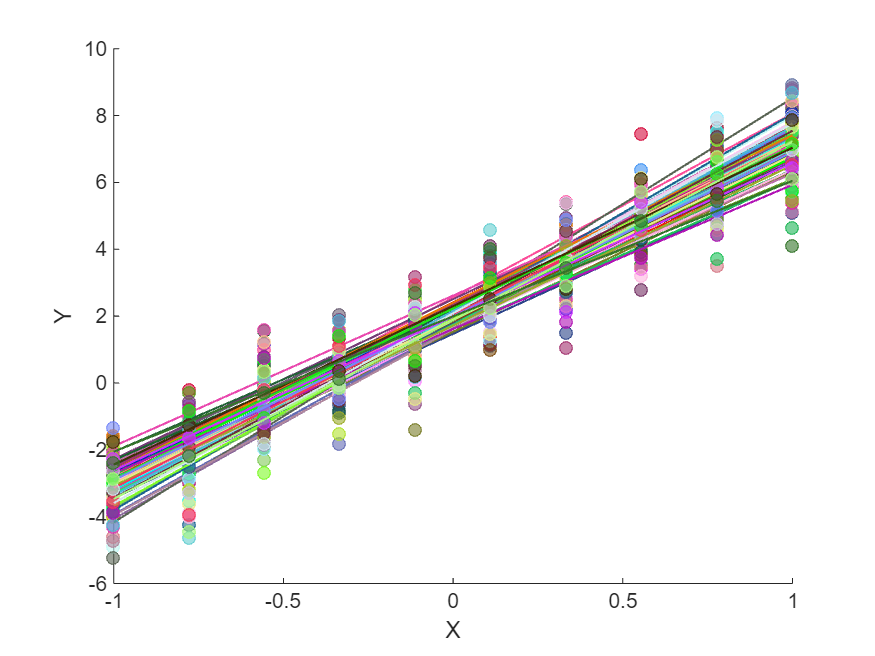

% строим зависимость вариации параметров модели от амплитуды ошибки
selection = 2;
b_str = "b_"+ string(selection);
ax = get_next_ax();

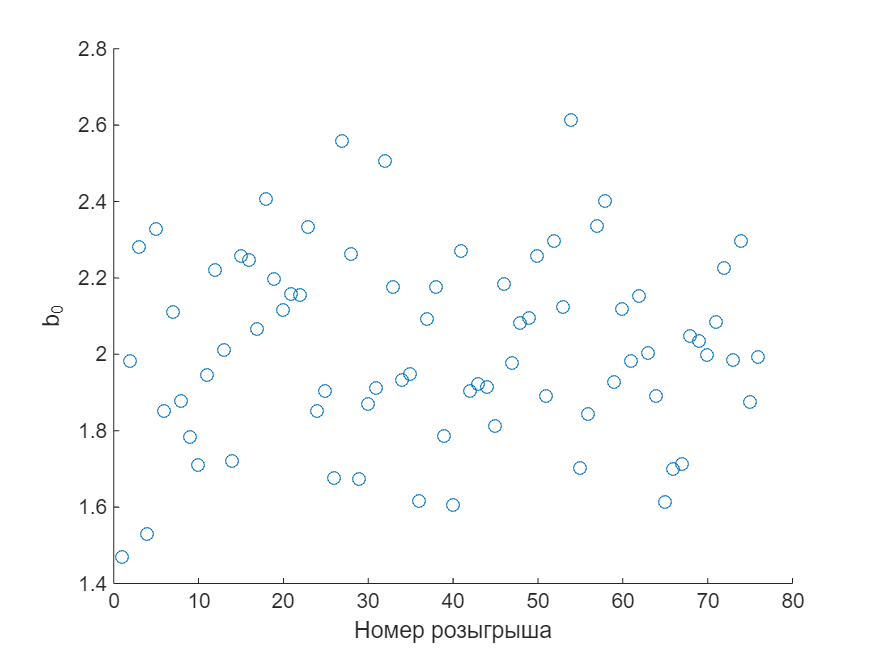

delta = [0.1,0.2,0.4,1]
b_std = cell(numel(delta),1);

hold(ax,"on")
for ii = 1:numel(delta)
    [~,~,beta_mat] = sampling_surf_plot(beta,101,201,delta(ii));
    b_mat_selected = beta_mat(:,:,selection);
    b_std{ii}=std(b_mat_selected,0,2);

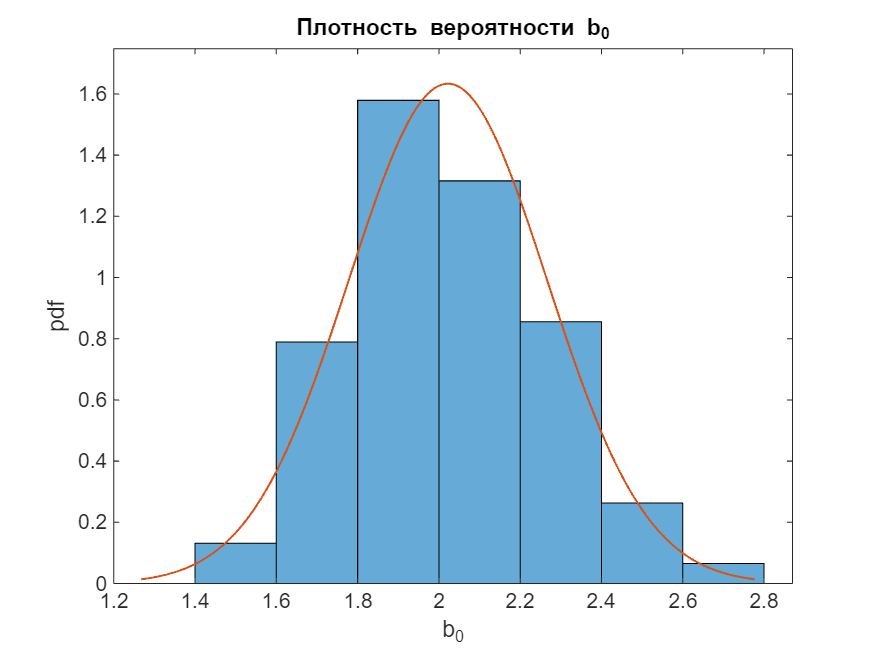

    plot(ax,sampling_volume,b_std{ii},"LineWidth",3);
end
hold(ax,"off")
lgd = legend(ax,string(delta(:)),"Location",'northeast');
lgd.Title.String = "\Delta ";
xlabel(ax,"Объем выборки");
ylabel(ax,"std("+b_str+")");

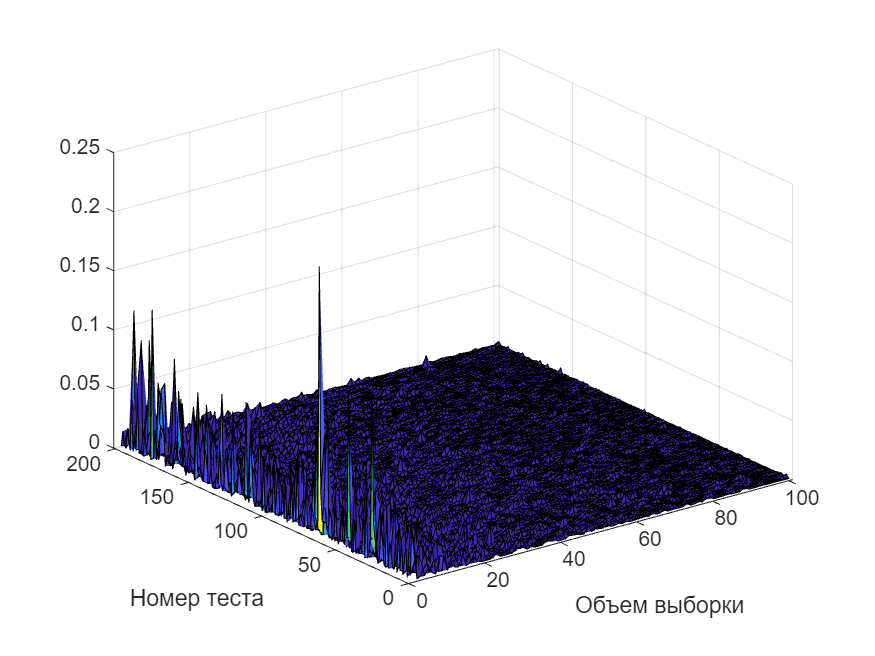


ax = get_next_ax();
hold(ax,"on")
for ii = 1:numel(delta)
    [~,~,beta_mat] = sampling_surf_plot(beta,101,201,delta(ii));
    b_mat_selected = beta_mat(:,:,selection);
    b_std{ii}=std(b_mat_selected,0,2);
    plot(ax,sampling_volume,b_std{ii}/delta(ii),"LineWidth",3);
end
title("Нормированное на вариацию ошибки")
hold(ax,"off");
lgd = legend(ax,string(delta(:)),"Location",'northeast');
lgd.Title.String = "\Delta ";
xlabel(ax,"Объем выборки");
ylabel(ax,"std("+b_str+")/\Delta");

Основной экспериментальный вывод, вариация коэффициентов регрессии прямо пропорциональна амлитуде ошибки исходных данных

**Обозначения статистических параметров**

Случайные величины, которые мы изучаем путем их розыгрыша (сэмплирования, выборки) характеризуются векторами этих сэмплов

Пусть, вектора $\vec{X}$и $\vec{Y}$ - вектора сэмплов случайно величины, N - количество измерений.

$\overline{X} = \vec{I}^T\vec{X}/N$, $\overline{Y} = \vec{I}^T\vec{Y}/N$ - среднее значение выборки, $\vec{I}$ - вединичный вектор (состоящий из единиц)

Квадратичные отклонения:


$$S_{XY}=[\vec{X} - \overline{X}\vec{I}]^T[\vec{Y} - \overline{Y}\vec{I}]=\vec{X}^T\vec{Y}-N \overline{X} \overline{Y}$$
 


$$S_{XX}=[\vec{X} - \overline{X}\vec{I}]^T[\vec{X} - \overline{X}\vec{I}]=\vec{X}^T\vec{X}-N \overline{X} ^2$$
 

Это по сути скалярное произведение, только каждый из векторов смещен оносительно своего среднего

Черточка сверху- среднее значение, стрелочка сверху - вектор.

$Var(\vec{X}) =S_{XX}/(N-1)$ - вариация,

Если сложить данные в матрицу $M=[\vec{X},\vec{Y}]$, то ковариация этой матрицы (это ковариация двух случайных скалярных величин, которые даются в виде вектор-столбцов их семплов, это не случайные вектора!) будет :


$$Cov(M)=[\vec{X},\vec{Y}][\matrix{\vec{X}^T\cr \vec{Y}^T}]=[\matrix{S_{XX}& S_{XY} \cr S__{YX} & S_{YY} }]/(N-1)$$


Таким образом, в матрице ковариации выборок двух случайных переменных на диагонали стоят вариации каждой из переменных, а вне диагонали ковариации.

clearvars
N=3;
X=randn(N,1);Y=randn(N,1);
cov([X,Y])

delta =     0.1000    0.2000    0.4000    1.0000


cov(X,Y)
X=X-mean(X);Y=Y-mean(Y);
[X'*X,Y'*X;
    X'*Y,Y'*Y]/(N-1)

Если случаные переменные некоррелированы, то их ковариация должна быть близка к нулю. Если коррелированы, то нет. Проведем простой эксперимент с бросанием монетки. 

У нас есть две монетки. Пусть орел  - это 1 , а решка 0. 

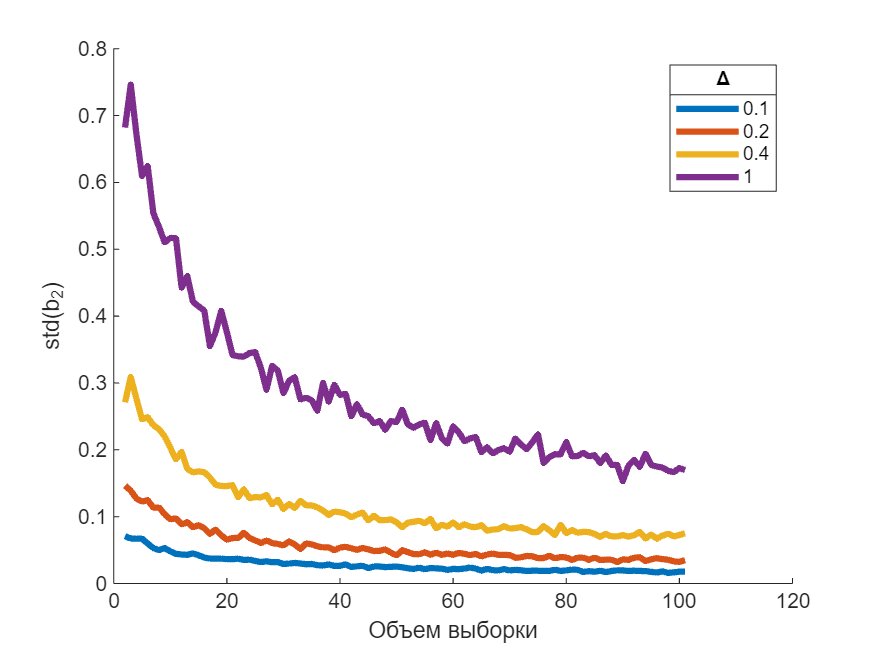

disp("Монетки независимы, ковариация равна нулю:")
clearvars
x1 = rand(1000,1)>0.5;
x2 = rand(1000,1)>0.5;
Sxy=(x1'*x2)/(999)

%Sxy=(x1-mean(x1))'*(x2-mean(x2))/(999)

clearvars
disp("Монетки склеены разноименными краями, ковариация не равна нулю:" )
x1 = rand(1000,1)>0.5;
x2 = ~x1;
%Sxy=(x1-mean(x1))'*(x2-mean(x2))/(999)
Sxy=(x1'*x2)/(999)

Как так-то?

**Регрессионная модель  нулевого порядка**

$X_{zero \ order}=[\vec{I}]$ - матрица предикторов состоит только из одного единичного столбца

 
$$\vec{b}=b_0=(X^TX)^{-1}X^T\vec{Y}=(\vec{I}^T\vec{I})^{-1}\vec{I}^T\vec{Y}=\frac{\sum_{i=1}^{N}y_i}{\sum_{i=1}^{N}1}=\frac{\sum_{i=1}^{N}y_i}{N}=\overline{Y}$$


Таким образом,  регреcсия нулевого порядка описывает зависимость $Y $от $X$ как среднее от имеющихся результатов наблюдения Y.

**Первый порядок (прямая линия)**

Матрица модели состоит всего из двух столбцов: $X_{first \ order}=[\vec{I},\vec{X}]$, соотвественно, $X_{first\ order}^T=[\matrix{\vec{I}^T\cr \vec{X}^T}]$ (напомню, что стрелочка в $\vec{a}$, обозначает всегда вектор-столбец) 

Обратим внимание, что $\vec{I}^T\vec{X}=N\overline{X}$,где черточка сверху $\overline{X}$ обозначает среднее арифметическое значение столбца.

 
$$\vec{b}=[\matrix{b_0\cr b_1}]=X_{first  \ order}^{\dagger}\vec{Y}=([\matrix{\vec{I}^T\cr \vec{X}^T}][\vec{I}, \vec{X}])^{-1}[\matrix{\vec{I}^T\cr \vec{X}^T}]\vec{Y}=([\matrix{N \ &  \vec{I}^T\vec{X} \ \cr \vec{X}^T\vec{I} & \vec{X}^T\vec{X}}])^{-1}[\matrix{\vec{I}^T\cr \vec{X}^T}]\vec{Y}$$


Учитывая, что (см) $\vec{X}^T\vec{X}=S_{XX}+N\overline{X}^2 $, а (см) $\vec{X}^T\vec{Y}=S_{XY}+N\overline{X}\overline{Y}$:

 
$$\vec{b}=[\matrix{N \ &  N\overline{X} \ 
            \cr N\overline{X} &S_{XX}+N\overline{X}^2 }]^{-1}   [\matrix{N\overline{Y} \cr S_{XY}+N\overline{X}\overline{Y}}]$$


| Обратную матрицу довольно легко инвертировать, формула для инвертирования матрицы 2х2 

$A^{-1}=[\matrix{a_{11} & a_{12} \cr a_{21} & a_{22}}]^{-1}=\frac{1}{det(A)}[\matrix {a_{22} & -a_{12} \cr -a_{21} & a_{11}}]$, где определитель $det(A) = a_{11}a_{22} - a_{21}a_{12} $

A=sym("a",[2 2]); 
inv(A)
det(A)
inv(A)*det(A)


$$det(X_{first \ order}^TX_{first \ order})=N\vec{X}^T\vec{X}- (\vec{I}^T\vec{X})^2 =N\vec{X}^T\vec{X}- (N \overline{X})^2=NS_{XX}$$


Тогда, с учетом формулы выше  (см) окончательно получим выражение для коэффициентов аппроксимации:


$$[\matrix{b_0\cr b_1}] =\frac{1}{N} S^{-1}_{XX} [\matrix{S_{XX}+N\overline{X}^2   \ &  -N\overline{X} \ \cr -N\overline{X}&  N }][\matrix{N\overline{Y}\cr S_{XY}+N\overline{X}\overline{Y}}]$$


Отсюда получаем очень простые выражения для коэффициентов аппроксимации:


$$b_1=\frac{1}{N} S^{-1}_{XX} [-N^2\overline{X}\overline{Y} + NS_{XY} + N^2\overline{X}\overline{Y}]=S^{-1}_{XX}{S_{XY}}$$



$$b_0=S^{-1}_{XX}[NS_{XX}\overline{Y}+N^2 \overline{X}^2 \overline{Y} - NS_{XY}\overline{X}-N^2   \overline{X}^2 \overline{Y}  ]=\overline{Y} - {S_{XX}^{-1}S_{XY}}\overline{X}=\overline{Y}-b_1\overline{X}$$


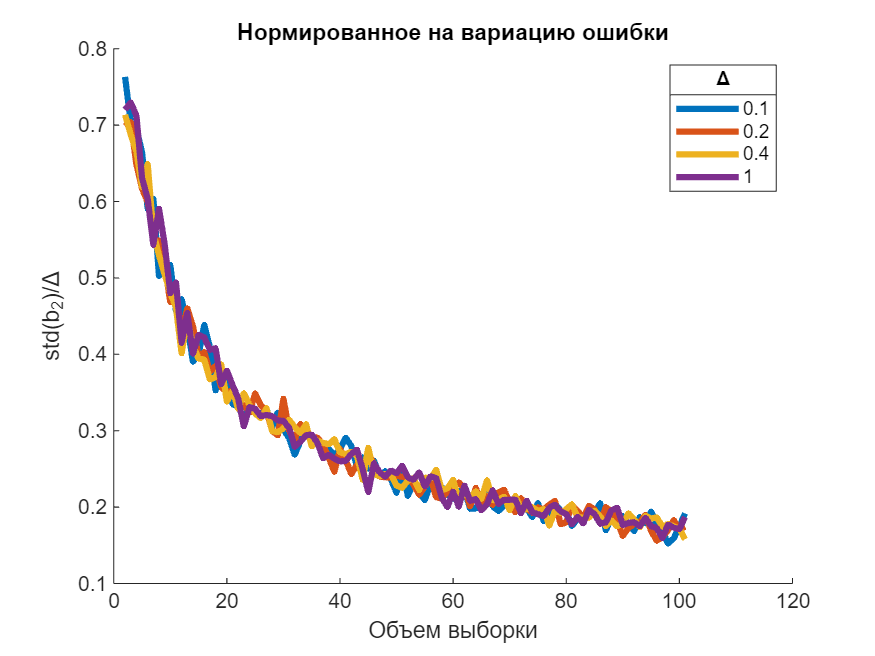

% проверка правильности выражений для расчета через ковариции и через
% псевдообратную матрицу

clearvars
N = 10
X = linspace(-1,1,N)';
Y = 0.0 + 0.43*X + 0.01*randn(10,1);
% через встроенную функцию:
Kxy = cov(X,Y) % матрица ковариации двух случайных переменных, представленных векторами их семплов одинаковго размера
% матричное выражение
[X,Y]'*[X,Y]/(N-1) % матрица ковариации двух случаных переменных X и Y
b1 = Kxy(1,2)/Kxy(1,1);
b0=mean(Y)-b1*mean(X);
b_vect_cov = [b0;b1] % через матрицу ковариации
% расчет через псевдообратную матрицу
I = ones(size(X));
b_vect_pseudoInverse = [I,X]\Y


$$\vec{\hat{Y}}=[\vec{I},\vec{X}] [\matrix {b_0\cr b_1}]=\vec{I}\overline{Y}-b_1\vec{I}\overline{X} + b_1\vec{X}$$



$$\vec{\hat{Y}} - \vec{I}\overline{Y}=b_1[\vec{X}-\vec{I}\overline{X}]={S_{XX}^{-1}S_{XY}}[\vec{X}-\vec{I}\overline{X}]$$


Формула расчета параметров модели через вариацию-ковариацию для линейной регрессии справедлива и для общего случая (когда у нас имеются несколько предикторов). Задача тогда формулируется как:


$$\vec{Y}=[\vec{I},\vec{X_1},\dots,\vec{X_P}][\matrix{b_0 \cr \vec{b_1} }]=[\vec{I},X][\matrix{b_0 \cr \vec{b_1} }]$$


Вектор параметров модели также дается выражением:


$$\vec{b_1}=S^{-1}_{XX}\vec{S}_{XY}$$



$$b_0=\overline{Y} - \vec{\overline{X}}^T\vec{b_1}$$


Однако, теперь:


$$S_{XX}=(X-\vec{I}\vec{\overline{X}}^T)^T(X-\vec{I}\vec{\overline{X}}^T)=X^TX - N\vec{\overline{X}}\vec{\overline{X}}^T=(N-1)Cov(X)$$



$$\vec{S}_{XY}=X^T\vec{Y}-N\vec{\overline{X}}\overline{Y}$$


$\vec{\overline{X}}$ - вектор-столбец средних значений предикторов. Подробный вывод см. отдельно.

clearvars
N=10
X1 = randn(N,1);
X2= randn(N,1);

ans =     1.5234    1.6316
    1.6316    2.1693


I = ones(size(X1));

ans =     1.5234    1.6316
    1.6316    2.1693


Y = 0.5 + 0.43*X1 + 0.61*X2+ 0.2*randn(N,1);
meanY=mean(Y)
X = [X1,X2];

ans =     1.5234    1.6316
    1.6316    2.1693


meanX = I*mean(X)

Sxy = (X-meanX)'*(Y-meanY)


Монетки независимы, ковариация равна нулю:


Sxx = (X-meanX)'*(X-meanX)

cov(X)*(N-1)
b1 = Sxx\Sxy;
b0=mean(Y)-mean(X)*b1

Sxy = -0.0149


b_vect_cov = [b0;b1]
b_vect_pseudoInverse= [I,X]\Y

Монетки склеены разноименными краями, ковариация не равна нулю:


Альтернативный вариант  - через матрицу ковариации всех переменных:


$$Cov([X,\vec{Y}]) =\frac{1}{N-1} [\matrix{(N-1)Cov(X)& \ \vec{S}_{XY} \cr \vec{S}_{XY}^T & S_{YY}} ]$$


clearvars
N=100
X1 = randn(N,1);X2= randn(N,1);Y = 0.5 + 0.43*X1 + 0.61*X2+ 0.2*randn(N,1); % генерим исходные данные
X = [X1,X2];

Sxy = 0

M = [X,Y]; % складываем все в одну табличку (матрицу свойств)
CovM = cov(M) % считаем ее ковариацию
b1_vec = CovM(1:2,1:2)\CovM(1:2,end) % находим коэффициенты предикторов
b0=mean(Y) - mean(X)*b1_vec % нашли dummy variable
% для сравнения тоже самое по формулам линейной алгебры:


#### Матрица ковариации параметров модели

Теперь вернемся к линейной регресси 


$$\vec{b}=X^{\dagger}\vec{Y}=X^{\dagger}X\vec{\beta} + X^{\dagger}\vec{\epsilon}=\vec{\beta} + X^{\dagger}\vec{\epsilon}$$


$\mathbb{E}[\vec{b}]=\vec{\beta}$, так как $X^{\dagger}X=(X^TX)^{-1}X^TX=I$, а $\mathbb{E}[\vec{\epsilon}]=\vec{0}$


$$Cov(\vec{b})=(\vec{\beta}-\vec{b})(\vec{\beta}-\vec{b})^T=((X^{\dagger}X-I)\vec{b} + X^{\dagger}\vec{\epsilon})((X^{\dagger}X-I)\vec{b} + X^{\dagger}\vec{\epsilon})^T=X^{\dagger}\vec{\epsilon}\vec{\epsilon}^T(X^{\dagger})^{T}$$



$$X^{\dag}Cov(\vec{\delta})X^{\dag^T}$$


Теперь воспользуемся тем, что вектор ошибки случайный и каждая точка независима от другой, и все они получены из нормального распределения  $\delta \sim \sigma^2 N(0,1)$  - означает, что $\delta$ получен из нормального распределения со средним значением равным нулю. Тогда ковариации будет диагональной: $Cov(\vec\delta)=[\matrix {\sigma^2 &...& 0\cr
0&\ddots&0\cr 0 &\dots &\sigma^2}]$


$$X^{\dag}Cov(\vec{\delta})X^{\dag^T}{}=X^{\dag}X^{\dag^T}{}\sigma^2=(X^TX)^{-1}\sigma^2$$


Последниц переъод следует из:


$$X^{\dag}X^{\dag^T}=(X^TX)^{-1}X^T[(X^TX)^{-1}X^T]^T=(X^TX)^{-1}X^TX[(X^TX)^{-1}]^T=[(X^TX)^{-1}]^T=(X^TX)^{-1}$$


Таким образом, окончательно получим выражение для матрицы ковариации параметров линейной регрессии:


$$Cov(\vec{\beta)}=(X^TX)^{-1}\sigma^2$$


В этой формуле мы использовали то, что ошибка распределена нормально и для каждой точки дисперсия этого распределения одинакова.

Матрица ковариации вектора параметров линейной регрессии


$$Cov(\vec{Y}_{interp})=X_{interp}Cov(\vec{\beta})X_{interp}^T$$


#### Небольшой численный эксперимент на предмет того, что такое доверительная вероятность.

% проведем численный эксперимент на выполнение статистики
clearvars
M = 1000;% количество тестов

$$ans = \left(\begin{array}{cc} \frac{a_{2,2}}{a_{1,1}\,a_{2,2}-a_{1,2}\,a_{2,1}} & -\frac{a_{1,2}}{a_{1,1}\,a_{2,2}-a_{1,2}\,a_{2,1}}\\ -\frac{a_{2,1}}{a_{1,1}\,a_{2,2}-a_{1,2}\,a_{2,1}} & \frac{a_{1,1}}{a_{1,1}\,a_{2,2}-a_{1,2}\,a_{2,1}} \end{array}\right)$$

N = 100;% количество точек в выборке

$$ans = a_{1,1}\,a_{2,2}-a_{1,2}\,a_{2,1}$$

beta2 = zeros(M,2);

$$ans = \left(\begin{array}{cc} a_{2,2} & -a_{1,2}\\ -a_{2,1} & a_{1,1} \end{array}\right)$$

P=2;% количество параметров регрессионной модели
for jj = 1:M
    x = randn(N,1);
    y = 1 + 2*x + randn(N,1);
    X = [ones(N,1),x];
    beta = X\y;
    e= X*beta - y;
    sigma = e'*e/(N-P);% считаем вариацию ошибки
    Cov_beta = (X'*X)\eye(P)*sigma;% считаем матрицу ковариации 
    Var_beta = diag(Cov_beta);% считаем вариацию (диагональные элементы матрицы ковраиации)

N = 10

    beta2(jj,:)=beta(2) + sqrt(Var_beta(2))*[1 -1];
end
sum((2<=beta2(:,1)) & (2>=beta2(:,2)))/M
d = fitdist(beta2(:,2),"Normal")

Kxy =     0.4527    0.1944
    0.1944    0.0836


plot(d)

### Проблема мультиколлинеарности и перебоучения, уменьшение размерности при помощи метода анализа главных компонент

Для примера рассмотрим последовательность работы PCA + линейная регрессия

- Разбиваем исходные данные на обучающую выборку и выборку для тестирования обученной модели 

- Проводим анализ "лишних" данных и выкидываем их при помощи метода анализа главных компонент

- Обучаем регрессионную модель на обучающей выборке

- Преобразуем данные для тестирования в базис ортогональной системы координат главных компонент

- Рассчитываем прогноз при помощи обученной модели

Данные  - табличка каких-то критериев, влияющих на кредитный рейтинг (изначально взяты из задачи классификации, но мы будем пользоваться ими для обучения и тестирования регрессионной модели).

Колонки с первой по седьмую - предикторы, рейтинг  - последняя колонка  - кредитный рейтинг в символьном виде, так как данные  - для решения задачи классификации (для регрессионной  модели преобразуем ее в числовое значение).

Наблюдения в первого по 100 - тестовые, со 101 до конца - для обучения.

creditrating = readtable(fullfile(get_folder(),'CreditRating_Historical.dat')); % данные взяты из хелпа по матлаб

ans =     0.4527    0.1944
    0.1944    0.0836


creditrating(1:5,:)
X = table2array(creditrating(:,2:7));
Y = cellfun(@(x)convert_rating_to_number(x),creditrating.Rating); % данные из примера использовались для задачи классификации

b_vect_cov =    -0.0008
    0.4294


Формирование обучающей выборки и выборки для тестирования предсказания модели:

% часть данных, на которых мы проводим обучение модели:
XTrain = X(101:end,:);%  - предикторы
YTrain =Y(101:end); % - зависимая переменная

b_vect_pseudoInverse =    -0.0008
    0.4294



% часть данных, которая будет исопльзоваться для предсказания модели
XTest = X(1:100,:);% матрица тестовых данных (данные на которых мы будем тестировать модель)
YTest = Y(1:100);% данные на которых 


Находим главные компоненты для набора обучения, будем пользоваться SVD разложением:


$$X_{train}=U\Sigma V^T$$


Напомню, что марица U - это ортонормированный базис пространства  столбцов, а $V$ - ортонормированный базис пространства строк. Соответственно, операция умножения исходной матрицы на левые сингулярные вектора приводит ее к нормированному базису.

mu_svd = mean(XTrain) % средние значения по каждому из столбцов
[U,S,V] = svd(XTrain -mu_svd,'econ'); % X = U*S*V'

N = 10

US = U*S;
norm((XTrain-mu_svd) - US*V')


$$X_{train}V=U\Sigma$$
 

Матрица, которая стоит в равенстве справа - это ортогональная матрица (так как $(U\Sigma)^TU\Sigma=\Sigma^TUU^T\Sigma=\Sigma^2$), но не ортонормированная, то есть, столбцы этой матрицы ортогональны, но их модули не равны единице.

Далее в соответствии с методом анализа главных компонент, мы 

Уменьшаем размерность задачи:

dimentionality = 2; % количество сингулярных значений
US_reduced = US(:,1:dimentionality);% уменьшаем размерность U*S
I = ones(size(US,1),1);

meanY = 0.4822

Решаем задачу регрессии - находим параметры модели

b =  [I,US_reduced]\YTrain

Раскладываем тестовые данные по базису правых сингулярных векторов 

US_test = (XTest-mu_svd)*V(:,1:dimentionality);

meanX =    -0.0753   -0.0379
   -0.0753   -0.0379
   -0.0753   -0.0379
   -0.0753   -0.0379
   -0.0753   -0.0379
   -0.0753   -0.0379
   -0.0753   -0.0379
   -0.0753   -0.0379
   -0.0753   -0.0379
   -0.0753   -0.0379


Рассчитываем предсказание модели

I = ones(size(US_test,1),1);

Sxy =     6.4533
    5.7869


Yprediction = [I,US_test]*b;
YTest - Yprediction;

Sxx =     8.2773    4.6875
    4.6875    6.6638


ax = get_next_ax();
plot(ax,YTest)

ans =     8.2773    4.6875
    4.6875    6.6638


hold(ax,"on")
plot(ax,Yprediction)

b0 = 0.5383

hold(ax,"off")

Это был, как бы низкоуровневый подход, мы применяли базовые функции линейной алгебры - сингулярное разложение и mldivide (которое работает по методу QR-факторизации), сейчас попробуем сделать тоже самое, но при помощи более высокоуровненовго подхода.

Далее будем использовать statistical toolbox, в котором есть большой арсенал функций для машинного обучения, в том числе для регрессионного анализа.

Мы будем пользоваться двумя функциями:

pca(Xtrain) - функция для анализа данных методом главных компонент, Xtrain - это, соотвественно, матрица предикторов для обучающей выборки

fitlm(scoreTrain,Xtrain) - эта функция проводит обучение регрессионной модели на scoreTrain обучащей выборке - зависимой переменной (это одна из колонок матрицы данных)

This code returns four outputs: `coeff`, `scoreTrain`, `explained`, and `mu`. 

Use `explained`  - показывает какую долю вариации обясняет данная компонента

Дальше мы обучим регрессионную модель 

 (percentage of total variance explained) to find the number of components required to explain at least 95% variability. Use `coeff` (principal component coefficients) and `mu` (estimated means of `XTrain`) to apply the PCA to a test data set. Use `scoreTrain` (principal component scores) instead of `XTrain` when you train a model. 

Display the percent variability explained by the principal components.

[coeff,scoreTrain,~,~,explained,mu] = pca(XTrain);% coeff - это матрица V,

b_vect_cov =     0.5383
    0.4784
    0.5319


В качестве входного аргумента - матрица предикторов, опционально можно передавать алгоритм (по умолчанию используется 'svd' , но может быть использован и алгоритм, основанный на спектральном разложении матрицы ковариации 'eig',  а также 'als', про последний написано, что он лучше работает с пропущенными значениями (например, NaN) , `centered`, `on

Функция pca возращает несколько выходных аргументов:

Первый, coeff - это коэффициенты 

mean(coeff./V)

b_vect_pseudoInverse =     0.5383
    0.4784
    0.5319


mean(US./scoreTrain)
explained % показывает в процентах объясняемую данной матрицей долю вариации

The first two components explain more than 95% of all variability. Find the number of components required to explain at least 95% variability.

idx = find(cumsum(explained)>95,1)

Train a classification tree using the first two components.

scoreTrain95 = scoreTrain(:,1:idx);

N = 100

%mdl = fitctree(scoreTrain95,YTrain);% классификационная модель 
mdl = fitlm(scoreTrain95,YTrain)
scoreTest95 = (XTest-mu)*coeff(:,1:idx);

Pass the trained model `mdl` and the transformed test data set `scoreTest` to the `predict` function to predict ratings for the test set.  

YTest_predicted = predict(mdl,scoreTest95);

CovM =     1.1244    0.0740    0.5384
    0.0740    1.0924    0.7062
    0.5384    0.7062    0.7043


norm(YTest_predicted - Yprediction) % расхождение между предсказаниями statistics toolbox и расчету при помощи базовых функций линейной алгебры

b1_vec =     0.4382
    0.6168


Мы любим примеры с картинками, поэтому попробуем, применить линейную регрессию для предсказания куска картинки. Теперь наше регрессионное уравнение будет иметь вид:


$$Y=XB+E$$


Сверху над $Y, B,E$ пропали стрелочки, так как теперь это матрицы

Столбцы матрицы $B$ - это вектора коэффициентов линейной регрессии, i-й столбец, соответственно, описывает нам i-й столбец матрицы Y. Для каждого столбца матрицы отклика мы находим вектор-столбец параметров линейной регрессии.

Будем рассматривать задачу следующим образом. Разделим картинку на четыре части

левая верхняя - будет матрица предикторов обучающей выборки (матрица $X$)

правая верхняя - матрица откликов (матрица $Y$)

левая  нижняя часть - матрица предикторов тестовой выборки ($X_{test}$ )

правая нижняя часть - матрица отклика тестовой выборки

Наша задача состоит в том, чтобы не значая правую нижнюю часть картинки ее пресказать при помощи линейной регрессионной модели, которую мы обучем на обучающей выборке (то есть на верхней картинке)

clearvars

b0 = 0.4984

% Import image
folder =  get_folder();
selected_image= "test1.jpg"; % 
figs_folder =folder + "\figs"; 
full_file = fullfile(figs_folder,selected_image);
figs = imread(full_file);
M = size(figs,1)-2;N = size(figs,2)-2;

data= double((im2gray(figs))); 
cut_size = [1,354,755];
data = data(cut_size(1):end,cut_size(2):cut_size(3));
imshow(uint8(data))
ax =gca;
title(ax,"Исходная картинка")
M = size(data,1);
N = size(data,2);
t_dims = [91,134]; % размер тестовой картинки

% test_image_dimentions 
Mlast = M-t_dims(1)-1; % число строк в обучающйе выборке
Nlast = N-t_dims(2)-1;% число столбцов предикторов в обучающей выборке
XTrain =data(1:Mlast,1:Nlast); % формируем матрицу предикторов
YTrain =data(1:Mlast,(Nlast+1):end); % формируем матрицу зависимой переменной
XTest = data((Mlast+1):end,1:Nlast);
YTest = data((Mlast+1):end,(Nlast+1):end);

ans = 0.6600

d =   NormalDistribution

  Normal distribution
       mu =  1.89459   [1.88793, 1.90125]
    sigma = 0.107379   [0.10287, 0.112304]


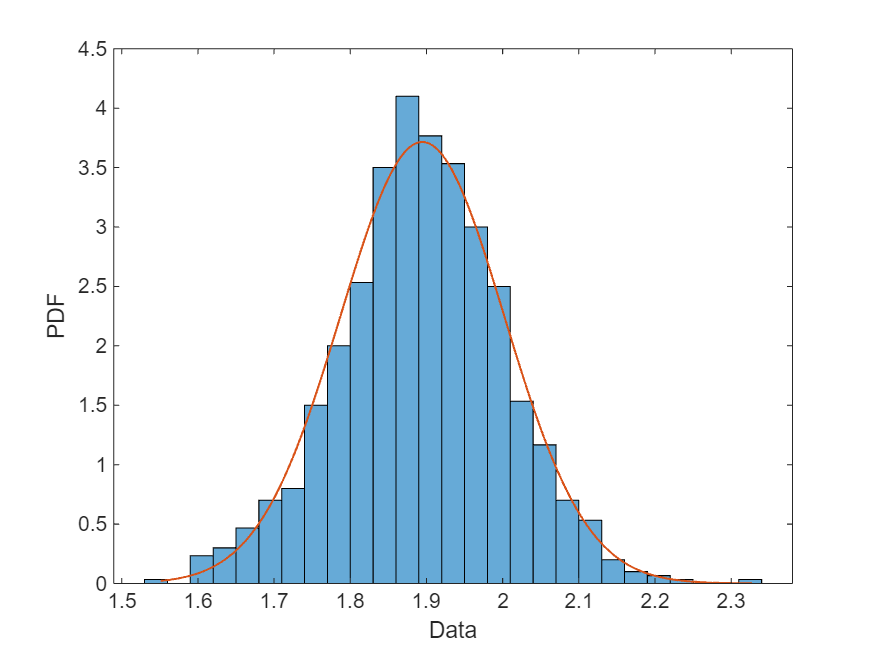

imshow(uint8(join_matrix(XTrain,YTrain,XTest,YTest,10,0)))

Itrain = ones(size(XTrain,1),1);
B1 = [Itrain,XTrain]\YTrain;
Ipred = ones(size(XTest,1),1);
Ypredicted1 =[Ipred, XTest]*B1;
disp("Линейная регрессия без уменьшения размерности матрицы предикторов:")
imshow(uint8(join_matrix(XTrain,YTrain,XTest,Ypredicted1,10,0)))

Добавляем метод главных компонент, чтобы понизить размерность матрицы предикторов обучающей выборки

% combined with pca
[coeff,scoreTrain,~,~,explained,mu] = pca(XTrain);% coeff - это матрица V,
mu_svd = mean(XTrain);% средние значения по каждому из столбцов

ans = 5×8 table
     ID      WC_TA    RE_TA    EBIT_TA    MVE_BVTD    S_TA     Industry    Rating 
    _____    _____    _____    _______    ________    _____    ________    _______

    62394    0.013    0.104     0.036      0.447      0.142        3       {'BB' }
    48608    0.232    0.335     0.062      1.969      0.281        8       {'A'  }
    42444    0.311    0.367     0.074      1.935      0.366        1       {'A'  }
    48631    0.194    0.263     0.062      1.017      0.228        4       {'BBB'}
    43768    0.121    0.413     0.057      3.647      0.466       12       {'AAA'}


%M= size(XTrain,1);
%N = size(XTrain,2);
[U,S,V] = svd(XTrain -mu_svd,'econ'); % X = U*S*V'
US = U*S;
MAX_S = size(S,1);

dimentionality = 4; % количество сингулярных значений
US_reduced = US(:,1:dimentionality);% уменьшаем размерность U*S
I = ones(size(US,1),1);
b =  [I,US_reduced]\YTrain;

Раскладываем тестовые данные по базису правых сингулярных векторов 

US_test = (XTest-mu_svd)*V(:,1:dimentionality);

mu_svd =     0.1405    0.2072    0.0515    2.0655    0.3074    6.3985


Рассчитываем предсказание модели

I = ones(size(US_test,1),1);
Yprediction = [I,US_test]*b;
disp("Линейная регрессия без уменьшения размерности матрицы предикторов:")

ans = 1.4741e-13

imshow(uint8(join_matrix(XTrain,YTrain,XTest,Yprediction,10,0)))

ЛИТЕРАТУРА

1. N.Draper, H.Smith . Applied regression analysis. Third edition. Wiley Series in Probability and Statistics. 

2.  Gilbert Strang - Introduction to Linear Algebra (2016, Wellesley-Cambridge Press)

3. John D'Errico (2025). Optimization Tips and Tricks (https://www.mathworks.com/matlabcentral/fileexchange/8553-optimization-tips-and-tricks), MATLAB Central File Exchange. Retrieved January 30, 2025.

#### Вывод формулы для коэффициентов линейной регрессии через статистические параметры

**Дополнение Шура (Schur complement) и инвертирование блочных матриц **

Если у нас есть блочная матрица вида:

$M=[\matrix{A \ & \ B \cr C \ & \ D}]$ ( то есть, матрица, у которой элементы - матрицы соотвествующего размера)

дополнение Шура  $Sh = D-CA^{-1}B$


$$[\matrix{A \ & \ B \cr C \ & \ D}]^{-1}=[\matrix{A^{-1}+ A^{-1}BSh^{-1}CA^{-1} & -A^{-1}BSh^{-1} \cr -Sh^{-1}CA^{-1}
& Sh^{-1} } ]$$


Формула справедлива когда матрицы $Sh$ и $A$- обратимы

[https://www.cis.upenn.edu/~jean/schur-comp.pdf](https://www.cis.upenn.edu/~jean/schur-comp.pdf)

#### Матричная форма линейной регрессии в статистической терминологии

Матрица модели: $X_{M}=[\vec{I}, X]$, теперь $X$ - матрица предикторов (размером *NxP*)

 $\vec{b}=[\matrix{b_0\cr \vec{b_1}}]=X_{M}^{\dagger}\vec{Y}=([\matrix{\vec{I}^T\cr X^T}][\vec{I}, X])^{-1}[\matrix{\vec{I}^T\cr X^T}]\vec{Y}=([\matrix{N \ &  \vec{I}^TX \ \cr X^T\vec{I} & X^TX}])^{-1}[\matrix{\vec{I}^T\cr X^T}]\vec{Y}$(*)

Вначале обратим внимание на кросс-диагональные 

элементы блочной матрицы:


$$\vec{I}^TX \frac{1}{N}=[\sum_{i=1}^NX_{i1},...,\sum_{i=1}^{N}X_{ij},...,\sum_{i=1}^{N}X_{i,P}]/N=[\overline{X}_1,...,\overline{X}_P]=\vec{\overline{X}}^T$$
 

То есть, $\vec{\overline{X}}$ - это вектор размером *Px1*, элементами которого являются средние значения столбцов матрицы $X$. С учетом этого, выражение (*) удобней переписать в виде:


$$[\matrix{b_0\cr \vec{b_1}}]=X_M^{\dagger}\vec{Y}=[X_M^{T}X_M]^{-1}X_M^T\vec{Y}=([\matrix{N \ &  N\vec{\overline{X}}^T \ \cr N\vec{\overline{X}} & X^TX}])^{-1}[\matrix{N\overline{Y}\cr X^T\vec{Y}}]$$


Вначале рассмотрим блочную матрицу $X_M^{T}X_M=[\matrix{N \ &  N\vec{\overline{X}}^T \ \cr N\vec{\overline{X}} & X^TX}]$.

Согласно формуле Шура, блочная матрица  $M=[\matrix{A &B\crС &D}]$ может быть инвертирована через  дополнение Шура: $Sh = D-СA^{-1}B$, $M^{-1}=[\matrix{A^{-1}+ A^{-1}BSh^{-1}CA^{-1} & -A^{-1}BSh^{-1} \cr -Sh^{-1}CA^{-1}
& Sh^{-1} } ]$

Для нашей конкретной матрицы:

$A^{-1}=\frac{1}{N}$ (просто скаляр), $B=N\vec{\overline{X}}^T$(вектор-строка),$C=N\vec{\overline{X}}$(вектор-столбец), $D=X^TX$(матрица PxP)


$$[X_M^TX_M]^{-1}=[\matrix{ N^{-1} +N^{-1}N\vec{\overline{X}}^TSh^{-1}N\vec{\overline{X}}N^{-1} \ & -N^{-1}N\vec{ \overline{X}}^TSh^{-1}\cr -Sh^{-1}N\vec{\overline{X}}N^{-1} & Sh^{-1}}]=[\matrix{ N^{-1} +\vec{\overline{X}}^TSh^{-1}\vec{\overline{X}} \ & \vec{ \overline{X}}^TSh^{-1}\cr -Sh^{-1}\vec{\overline{X}} & Sh^{-1}}]$$



$$[\matrix{b_0\cr \vec{b_1}}]=[X_M^{T}X_M]^{-1}X_M^T\vec{Y}=[\matrix{ N^{-1} +\vec{\overline{X}}^TSh^{-1}\vec{\overline{X}} \ & \vec{ \overline{X}}^TSh^{-1}\cr -Sh^{-1}\vec{\overline{X}} & Sh^{-1}}][\matrix{N\overline{Y}\cr X^T\vec{Y}}]$$


Посмотрим внимательно на выражение для вектора параметров $\vec{b_1}$:


$$\vec{b_1} = Sh^{-1}[ X^T\vec{Y}-N\vec{\overline{X}}\overline{Y}]$$


Оно  напоминает выражение для $b_1$ из формулы для прямой линии, только там $b_1$ - это был скаляр. Выражение в квадратных скобках имеет похожий смысл, как и выражение для Sxy, там $\vec{X}$ и $\vec{Y}$ были векторами, а их средние значения - скалярами, теперь $X$ - это матрица,  $\vec{\overline{X}}$ - вектор-столбец средних значений матрицы $X$ в каждом из столбцов. $X^T\vec{Y}$ - вектор, каждый элемент которого - скалярное произведение столбца матрицы $X$ на вектор $\vec{Y}$, вектор $\vec{\overline{X}}\overline{Y}$ - вектор, каждый элемент которого - произведение среднего значения столбца на $\overline{Y}$, то есть, среднее значения  зависимой переменной $\vec{Y}$. 

Теперь рассмотрим подробнее на дополнение Шура:

$Sh=X^TX- X^T\vec{I}\frac{1}{N}\vec{I}^TX$ - это матрица размером *PxP*.

С учетом определения вектор-столбца средних, его можно переписать в виде:


$$Sh = X^TX - N\vec{\overline{X}}\vec{\overline{X}}^T$$


Данное выражение практически полностью совпадает с выражением для $S_{XX}$, когда рассматрицалась одномерная задача. 

Обозначим $\overline{X}=\vec{\overline{X}}\vec{\overline{X}}^T$ матрицу размером *PxP*, элемент этой матрицы, стоящий на i-й строке j-го столбца равен произведению средних значений этих столбцов:


$$\overline{X}_{ij}=\overline{X_i} \ \overline{X_j}$$


% убедимся в том, что выражения действительно совпадают
clearvars
N=3
X=sym("X",[N 2],"real"); 
I = sym(ones(N,1))
Xmean = simplify(X'*I*I'*X)/N 

b =     6.8319
   -0.2182
    0.0114


XmeanV = mean(X)'% функция mean автоматически считает среднее в каждой колонке
simplify(N*XmeanV*XmeanV' - Xmean)

Теперь, что такое $X^TX$, это матрица, в которой на i-й строке j-го столбца стоит скалярное произведение i-го столбца на j-й столбец матрицы X


$$[X^TX]_{ij}=\vec{X_i}^T\vec{X_j}$$


Таким образом, дополнение Шура - это матрица, в которой на i-й строке j-го столбца стоит:


$$[Sh]_{ij}=\vec{X_i}^T\vec{X_j} - N\overline{X_i} \ \overline{X_j}$$


% убедимся в том, что выражения действительно совпадают
clearvars
N=3
X=sym("X",[N 2],"real"); 
I = sym(ones(N,1))
Xmean = simplify(X'*I*I'*X)/N 
XmeanV = mean(X)'% функция mean автоматически считает среднее в каждой колонке
simplify(N*XmeanV*XmeanV' - Xmean)

Видно, что это матрица ковариации (умноженная на число измерений) матрицы, в которой столбцы  - это сэмлы случайной величины:


$$Sh=(N-1)Cov(X)$$


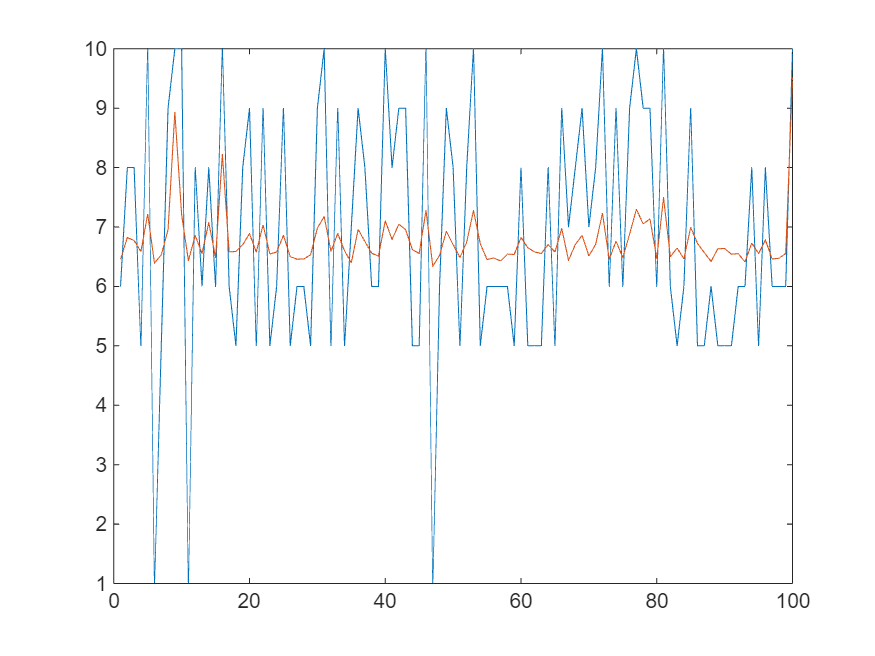

% убедимся в том, что выражения действительно совпадают

clearvars
N=3
X=sym("X",[N 2],"real"); 
XmeanV = mean(X)'% функция mean автоматически считает среднее в каждой колонке
Sh = simplify(X'*X - N*XmeanV*XmeanV')
Sigma= cov(X)*(N-1)
simplify(Sh-Sigma) % убеждаемся, что это матрица ковариации


Таким образом, окончательное выражение для вектора параметров линейной регрессии:


$$\vec{b_1} = [X^TX - N\vec{\overline{X}}\vec{\overline{X}}^T]^{-1}[ X^T\vec{Y}-N\vec{\overline{X}}\overline{Y}]$$


function M = join_matrix(UL,UR,DL,DR,w,val)
% функция скледивает четыре матрицы в одну, вставляя между ними нул, так,
% чтобы была рамка на картинке
    arguments
        UL

ans =     -1     1    -1     1     1     1


        UR

ans =     -1     1    -1     1     1     1


        DL

explained =    58.2614
   41.2606
    0.3875
    0.0632
    0.0269
    0.0005


        DR
        w = 10

idx = 2

        val = 0;
    end
    r1 = size(UL,1);r2 = size(DL,1);
    c1 = size(DL,2);c2 = size(DR,2);

mdl = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate       SE        tStat       pValue   
                   ________    _________    ______    ___________

    (Intercept)      6.8319     0.030216    226.11              0
    x1               0.2182    0.0073684    29.613    1.0238e-173
    x2             0.011369    0.0087558    1.2985        0.19421


Number of observations: 3832, Error degrees of freedom: 3829
Root Mean Squared Error: 1.87
R-squared: 0.187,  Adjusted R-Squared: 0.186
F-statistic vs. constant model: 439, p-value = 1.73e-172

    M = ones(r1+r2+w,c1+c2+w)*val;
    M(1:r1,1:c1) = UL;
    M(1:r1,(c1+w+1):end)=UR;
    M((r1+w+1):end,1:c1) = DL;

ans = 5.3439e-14

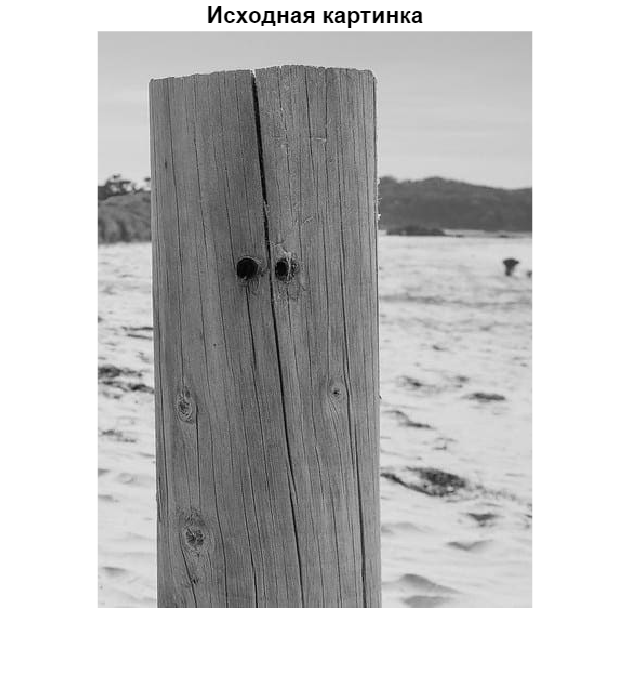

    M((r1+w+1):end,(c1+w+1):end) = DR;   
end
function rus_name = rus(type)
    possible_types =  ["stand" "legA" "trig" "legP" "custom"];
    possible_rus_names = ["Стандартный базис" "Присоединенные полиномы Лежандра" "Тригонометрический базис" "Полиномы лежандра" "Кастомный"];
    flag = possible_types==type;
    if any(flag)
        rus_name = possible_rus_names(flag);
    else
        rus_name = type;
    end

end
function val = convert_rating_to_number(rating)
    %rating = string(rating);
    switch rating(1)
        case "A"
            val = 7+count(rating,"A");
        case "B"
            val = 8-count(rating,"B");
        case "C"
            val = 4-count(rating,"C");
    end
end
function f = norm_distribution_function(mu,sig)
% возвращает анонимную функцию для нормального распределения
    f =@(x) exp(-(x-mu).^2./(2*sig^2))./(sig*sqrt(2*pi));

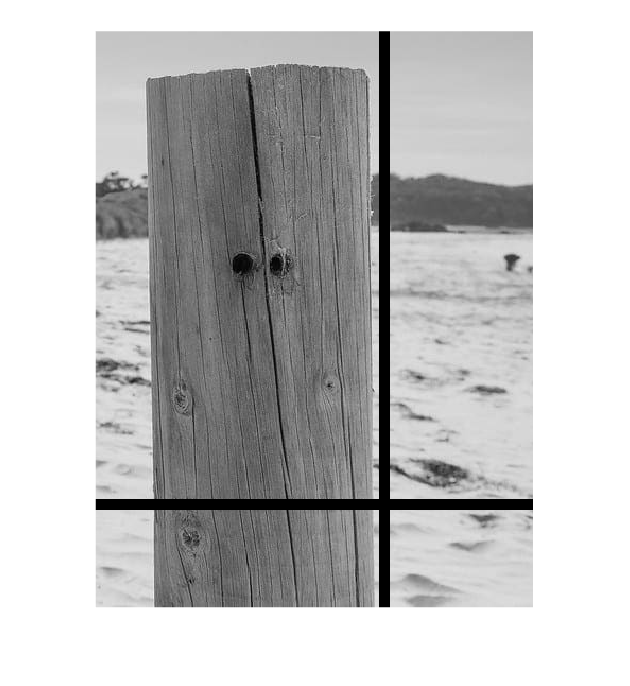

end
function [V,s] = vandermatrix(t,P,type,polyprod_function)
arguments
    t double
    P (1,1) double {mustBeInteger,mustBePositive} = 2
    type (1,1) string {mustBeMember(type,["stand" "legA" "trig" "legP" "custom"])} = "stand"
    polyprod_function =[]
end
% создаем матрицу Вандермонда
% type - тип полинома (стандартный базис, полиномы лежандра,
% тригонометрические полиномы)
    t = t(:);
    N = numel(t);

    V = zeros(N,P);
    if ~(type=="custom")
        [Pfun,s] = producing_function(type,t); % возвращаем производящую функцию для колонки матрицы вандермонда
    else
        assert(~isempty(polyprod_function)||~isa(polyprod_function,"function_handle"),"Если выбрана кастомная производящая функция, то нужно ее предоставить")

Линейная регрессия без уменьшения размерности матрицы предикторов:


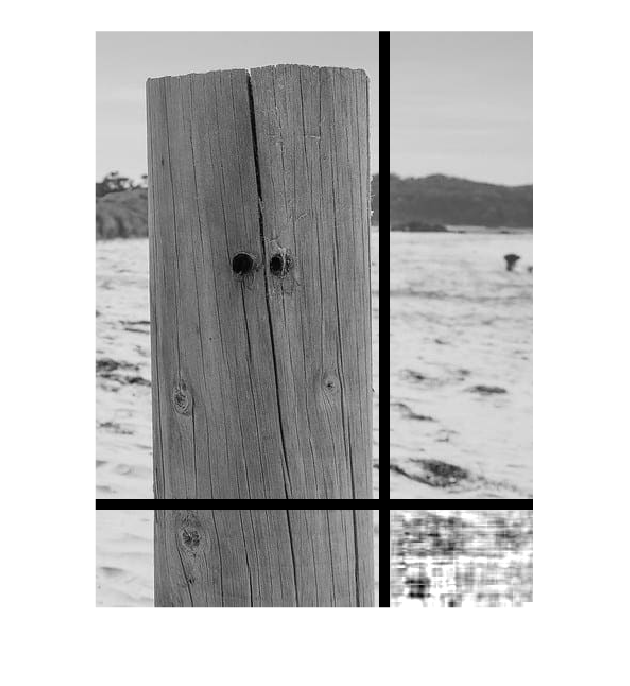

        s = normalize(t);

        Pfun = @(i)polyprod_function(i,s.x);
    end
    for jj = P:-1:1
        V(:,jj) = Pfun(jj);
    end
end
function dist= make_dist(type,options)
% возращает генератор N случайных чисел, распределенных в соответствии 
% с двух параметрическими распределениями: нормальным, дельта-равномерным,
% Вейбулла и Хи-квадрат
    arguments
        type (1,1) string {mustBeMember(type,["Normal" "Uniform" "Weibull" "Chi2"])}
        options.mu (1,1) =0
        options.sig (1,1)=0
    end
    mu=options.mu;
    sig2=options.sig^2;
    switch type
        case "Normal"
            dist = @(N) mu + sig2*randn([N 1]);

Линейная регрессия без уменьшения размерности матрицы предикторов:


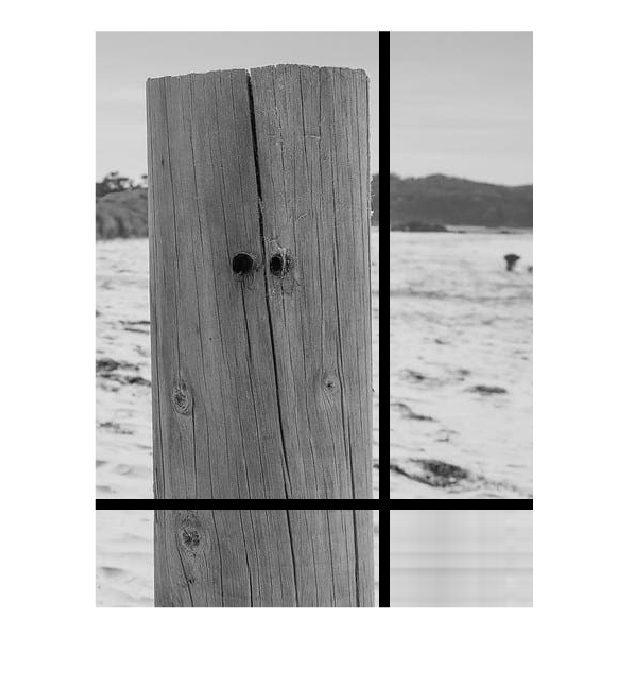

        case "Uniform"

            dist  = @(N)   sqrt(sig2)*(rand([N 1])  -0.5)+ mu;
        case "Weibull"
            dist  = @(N) wblrnd(mu,sqrt(sig2),N,1);
        case "Chi2"
            dist = @(N) (mu + sig2*randn([N 1]).^2);
    end

end
function norm_struct = normalize2(t)
% функция возвращает стурктуру, в которой хранятся данные для нормировки
    if ~issorted(t)
        t = sort(t,"ascend"); 
    end
    tmin = t(1);
    tmax = t(end);
    x = 2.0*((t - tmin) / (tmax - tmin))- 1; 
    norm_struct = struct("tmin",tmin,"tmax",tmax,"x",x); %t,(max(t) - min(t))    
end
function t = denormalize2(s)
    t = 0.5*(s.x + 1.0)*(s.tmax - s.tmin) + s.tmin;
end
function Pn = leg_polyA(i,t) % производящая функция для присоединенных полиномов Лежандра 
    persistent P 
    persistent tleg
    leg_type = 'norm';
    if isempty(tleg)||isempty(P)||(~isequal(t,tleg))
        P = transpose(legendre(i-1,t,leg_type)); % встроенная функция по сути возвращает уже матрицу Вандермонда
        tleg = t;
    end
    if i<=size(P,2)
        Pn = P(:,i);
        return
    end
    P = transpose(legendre(i,t,leg_type));
    tleg = t;
    Pn = P(:,end);
end
function Pn = trig_poly(i,t) % производящая функция для тригонометрических полиномов
    if i==1
        Pn  = ones(size(t));
        return
    end
    if mod(i,2)==0
        Pn = cos(i*t*pi);
    else
        Pn = sin(i*t*pi);
    end
end
function [P,s] = producing_function(type,t)
% функция возвращает производящую функцию для полинома
    s = normalize2(t);
    switch type
        case "stand" % стандартный базис полинома
          P = @(i) s.x.^(i-1);  
        case "legA" % присоединенные полиномы Лежандра
          P = @(i) leg_polyA(i,s.x); 
        case "legP" % полиномы Лежандра
          P = @(i) legendreP(i-1,s.x) ; % стандартная фукнция для полиномов лежандра
        case "trig" % тригонометрический базис
          P = @(i) trig_poly(i,s.x);  

    end
    
end
function [new_ax,fig_handle] = get_next_ax(index, axes_name_value_pairs)
% функция, которая возвращает новые оси на новой фигуре (нужна чтобы
% кратинки в ливскрипте нормально строились)
    arguments
        index = []
        axes_name_value_pairs cell = {}
    end
    persistent N;
    if isempty(index)
        if isempty(N)
            N=1;
        else
            N  = N+1;
        end
        fig_handle = figure(N);        
        clf(fig_handle);
        new_ax = axes(fig_handle,axes_name_value_pairs{:});
        %disp("fig"+ N)
    else
        fig_handle = figure(index);
        clf(fig_handle);
        new_ax = axes(fig_handle,axes_name_value_pairs{:});    
    end
end
function ax = get_named_ax(title_string)
    ax = get_next_ax();
    title(title_string);
end
function ax = draw_vector(ax,ttl,names,type,varargin)
% функция строит двух- и трех-мерные вектора, а также рассеянные данные из
% матрицы
% ax - оси (если пустые, то создаются новые)
% ttl - заголовок картинки
% names - имена векторов
% type:
%       "vector" - аргументы, которые передаются после интерпретируются
%                   как отдельные вектора
%       "point"  - в этом случае передается матрица в качестве аргумента и
%       столбцы матрицы строятся при помощи функций scatter и scatter3 d
%       в зависимости от размерности массива
    arguments
        ax =[]
        ttl string =strings(0,1)
        names string =strings(0,1)
        type string {mustBeMember(type,["vector" "point"])}="vector"
    end
    arguments (Repeating)
        varargin double
    end
    was_empty = isempty(ax); % это признак того, что все строится на новых осях
    if was_empty
        ax = get_next_ax();
    else
        hold(ax,"on");
        % if ~isempty(ax.Legend)
        %     leg_before = ax.Legend.String;
        % else
        %     leg_before = strings(0,1);
        % end
    end
    
    if strcmp(type,"vector")
        is_3D = numel(varargin{1})==3;
            if is_3D
                [x,y,z]  = make_xy(varargin{1});
                plot3(ax,x,y,z,'LineWidth',2,'Marker','o');
                hold on 
                for iii = 2:numel(varargin)
                        [x,y,z] = make_xy(varargin{iii});
                        plot3(ax,x,y,z,'LineWidth',2,'Marker','o');
                end
                grid on
                hold off                
            else
                [x,y]  = make_xy(varargin{1});
                plot(ax,x,y,'LineWidth',2,'Marker','o');
                hold on 
                for iii = 2:numel(varargin)
                        [x,y]  = make_xy(varargin{iii});
                        plot(ax,x,y,'LineWidth',2,'Marker','o');
                end
                grid on
                hold off
            end
            if isempty(names)||(numel(names)~=numel(varargin))
                legend(ax,string(1:numel(varargin)));
                
            else
                % if ~was_empty
                %      names= [names(:);leg_before(:)];
                % end
                legend(ax,names);
            end
            xlim(ax,[-1 1]);
            ylim(ax,[-1 1]);
            if ~isempty(ttl)
                title(ax,ttl);
            end
    else
        %data_number = numel(varargin); % число массивов данных
        is_3D = numel(varargin)==3;
        data = varargin{1};
        if size(data,2)>1
            data = transpose(data);
            is_transpose = true;
        else
            is_transpose = false;
        end
        if ~is_transpose
            for iii = 2:numel(varargin)
                data = [data,varargin{iii}];
            end
        else
            for iii = 2:numel(varargin)
                data = [data,transpose(varargin{iii})];
            end            
        end

        if is_3D
            scatter3(ax,data(:,1),data(:,2),data(:,3));
        else
            scatter(ax,data(:,1),data(:,2));
        end

    end
    if ~was_empty
            hold(ax,"off");
    end
end
function [x,y,z]  = make_xy(col)
% добавляет к координатам вектора нули так, чтобы при помощи функции plot
% строилась линия
    switch numel(col)
        case 1
            x = [col(1)];
            y = 0;
            z = 0;
        case 2
            x = [0 col(1)];
            y = [0 col(2)];
            z = zeros(1,2);
        case 3
            x = [0 col(1)];
            y = [0 col(2)];
            z = [0 col(3)];
    end
end
function folder = get_folder()
% текущая папка
folder = fileparts(matlab.desktop.editor.getActiveFilename);
end
function [sampling_volume,tests_number,beta_mat] = sampling_surf_plot(beta,Nmax,Mmax,delta)
        % N
        P = numel(beta);
        sampling_volume = 2:Nmax;
        tests_number = 2:Mmax;
        beta_mat = zeros([Nmax-1,Mmax-1,P]);
        for N=sampling_volume % первый индекс - объем выборки
            x = transpose(linspace(-1,1,N));% столбец координат
            X = vandermatrix(x,P); % матрица вандермонда
            Yo = X*beta;% истинное значение 
            for ii = tests_number% второй индекс - номер теста
                Y = Yo + delta*randn(N,1);
                b_values = X\Y;
                beta_mat(N-1,ii-1,:) = b_values;
            end
        end
end